clear all 
clc

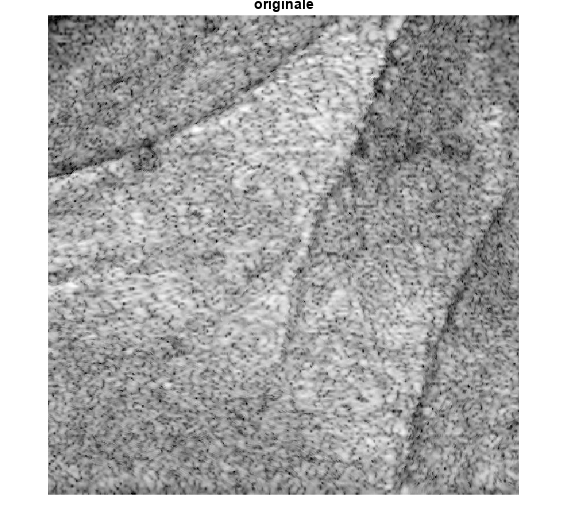

im = fullfile("imageGeneratedFrom3D/Luongo_1_rimozioneRes_000/immagine_5_0.2772.jpg");
I = imread(im);
originale = I;
imshow(I);title('originale');figure;

istogramma = imhist(I);
[value, idx] = max(istogramma);
centralValue = size(istogramma,1)/2 - idx;

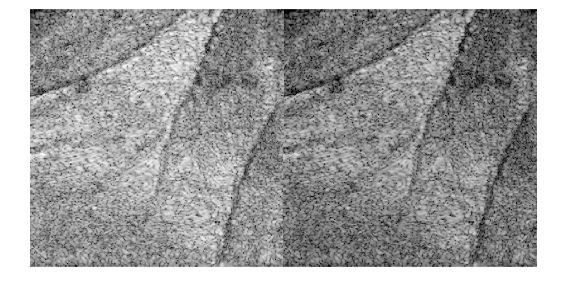

K = I+centralValue;
montage({I K})

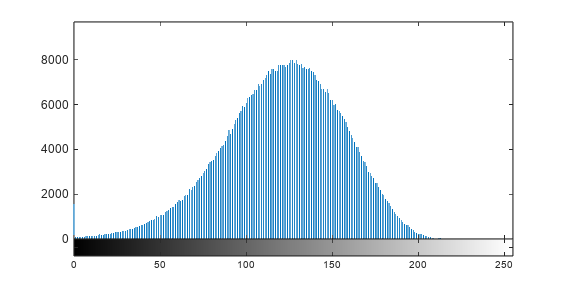

imhist(K);

J = histeq(K, [220 255]);

Display the original image and the adjusted image.

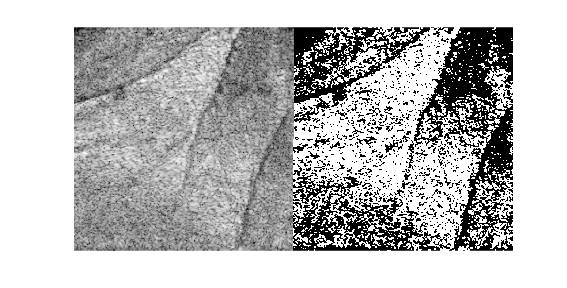

imshowpair(I,J,'montage')
axis off

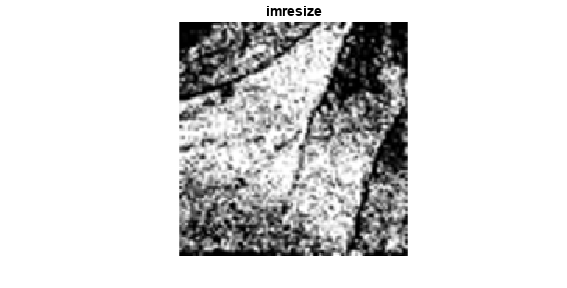

%RESIZE DELL'IMMAGINE
im1=imresize(J, 0.1, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
im1=imresize(im1, 2, 'bicubic');
imshow(im1);title('imresize');figure;

[dim1, dim2] = size(im1);
fprintf('Dimensione immagine: %.0f x %.0f', dim1, dim2);

Dimensione immagine: 168 x 164

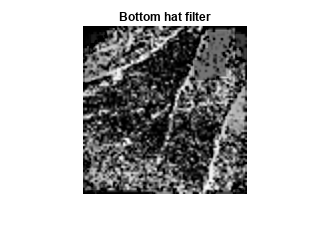

%APPLICAZIONE FILTRO DoG
% gaussian1 = fspecial('gaussian',15,14); 
% gaussian2 = fspecial('gaussian',15,15);
% gaussian = gaussian2 - gaussian1;
% dogFilterImage2 = conv2(double(im1), gaussian, 'same');
% imshow(dogFilterImage2,[]);title('DoGfilter');figure;

se = strel('square',20);
% dogFilterImage2 = ...
%     imsubtract(imadd(im1,imtophat(im1,se)),...
%     imbothat(im1,se));
dogFilterImage2 = imbothat(im1, se);
imshow(dogFilterImage2,[]);title('Bottom hat filter');figure;

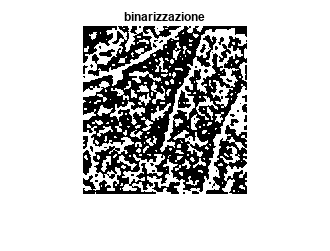

%BINARIZZAZIONE
A = dogFilterImage2;
% meanValue=mean2(A);
meanValue = imbinarize(A, "adaptive", "ForegroundPolarity","bright");
% threshold = meanValue*1.6; %più è alto il fattore di scala meno dettagli saranno presenti
% 
% A_bw = A > threshold;
imshow(meanValue); title('binarizzazione'); figure;

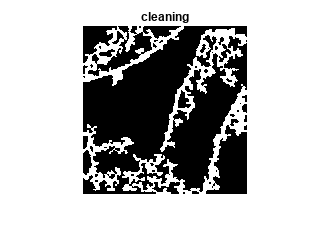

%CLEANING
CC= bwconncomp(meanValue);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW2 = ismember(L, find([S.Area] >= 800));
imshow(BW2); title('cleaning'); figure;

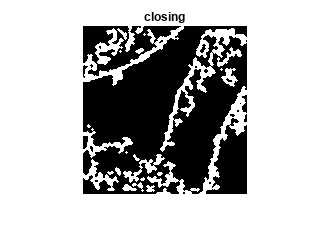

%CLOSING
se=strel('disk',1);
closing=imopen(BW2, se);
imshow(closing); title('closing'); figure;

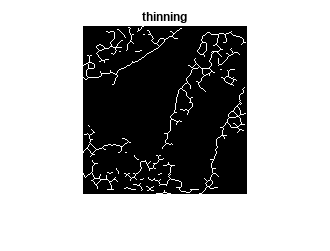

%THINNING
thinning= bwmorph(closing, 'thin', inf);
imshow(thinning);title('thinning');figure;

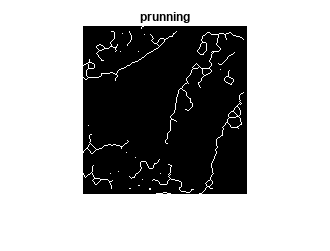

%PRUNNING
prun= bwmorph( thinning, 'spur', 5);
imshow(prun);title('prunning');figure;

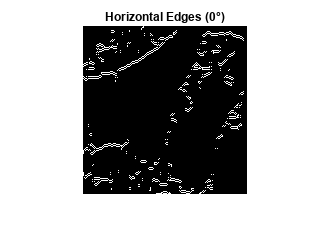

% Apply Sobel edge detection along the horizontal direction (0°)
horizontalEdges = edge(prun, 'Sobel', 'horizontal');

% Apply Sobel edge detection along the vertical direction (90°)
verticalEdges = edge(prun, 'Sobel', 'vertical');

% Perform a diagonal scan from the top-left to the bottom-right (180°)
diagonalEdges = edge(prun, 'Sobel', 'both');

% Perform a reverse diagonal scan from the top-right to the bottom-left (270°)
reverseDiagonalEdges = edge(flip(prun, 2), 'Sobel', 'both');

% Flip the reverseDiagonalEdges back to the original orientation
reverseDiagonalEdges = flip(reverseDiagonalEdges, 2);

% Sum all the binary images to get the combined edge information
combinedEdges = horizontalEdges + verticalEdges + diagonalEdges + reverseDiagonalEdges;

% Display the results
% figure; imshow(BWz); title('Original Image');
figure; imshow(horizontalEdges); title('Horizontal Edges (0°)');

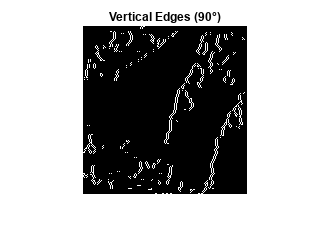

figure; imshow(verticalEdges); title('Vertical Edges (90°)');

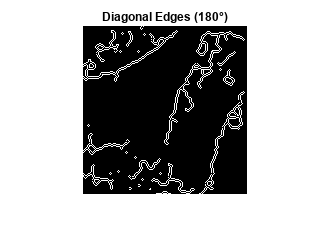

figure; imshow(diagonalEdges); title('Diagonal Edges (180°)');

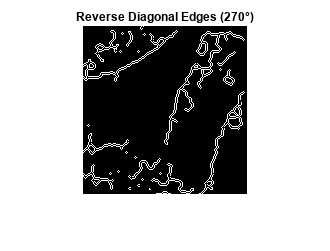

figure; imshow(reverseDiagonalEdges); title('Reverse Diagonal Edges (270°)');

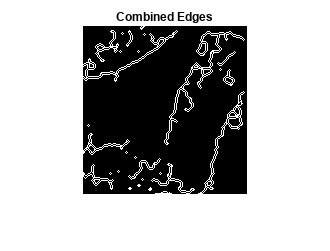

figure; imshow(combinedEdges); title('Combined Edges');

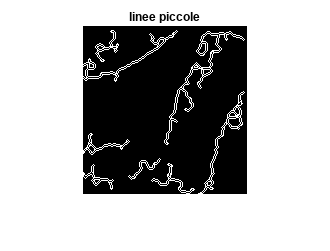

%CLEANING LINEE PICCOLE
BWz = bwareaopen(combinedEdges, 80);
imshow(BWz);title('linee piccole');figure;

% % FILLING
% filling= imfill(BWz, 'holes');
% imshow(filling);title('filling');figure;

% %DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
% dilatation_mask= strel('disk', 1);
% dilatedImageDat= imdilate(BWz, dilatation_mask);
% imshow(dilatedImageDat); title('dilatazione'); figure;

originale = imresize(originale, 0.2, 'bicubic');
rgbImage = cat(3, originale, originale, originale);

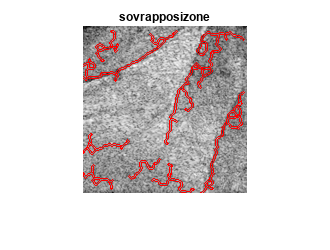


%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
clear m n1

[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  BWz(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=0;
        rgbImage(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage);title('sovrapposizone'); figure;